addpath('./functions');
addpath('./data');

[XTrain, YTrain, XTest, YTest] = load_data('data');

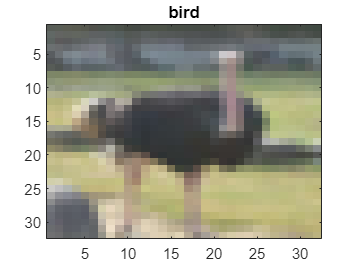

labels_names = ["Airplane", ...
                "Automobile", ...
                "Bird", ...
                "Cat", ...
                "Deer", ...
                "Dog", ...
                "Frog", ...
                "Horse", ...
                "Ship", ...
                "Truck", ...
                ];

labels_numbers = ["0", ...
                  "1", ...
                  "2", ...
                  "3", ...
                  "4", ...
                  "5", ...
                  "6", ...
                  "7", ...
                  "8", ...
                  "9", ...
                  ];

label2name = dictionary(labels_numbers, labels_names);
idx = randi(size(XTrain,4));

imagesc(XTrain(:,:,:,idx))
title(YTrain(idx))

% size(permutedImageData)
% test_size = 0.2
% % normalizedData = normalize(permutedImageData);
% [X_train, X_val, Y_train, Y_val] = train_test_split(permutedImageData, categoricalLabels, test_size);

% layers = basic_cnn_classifier()
% options = trainingOptions('sgdm', "ExecutionEnvironment","gpu",Plots="training-progress", MiniBatchSize=64, InitialLearnRate=0.001, MaxEpochs=10);
% net = trainNetwork(permutedImageData,categoricalLabels, layers, options);

% preds = net.classify(testData);
% tp = nnz(preds == testLabels);
% accuracy = tp / length(testLabels);
% disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

% layers = improved_cnn_classifier();
% options = trainingOptions('sgdm', "ExecutionEnvironment","gpu",Shuffle="every-epoch",Plots="training-progress", MiniBatchSize=64, InitialLearnRate=0.0001, MaxEpochs=30);
% net = trainNetwork(permutedImageData,categoricalLabels, layers, options);

% preds = net.classify(testData);
% tp = nnz(preds == testLabels);
% accuracy = tp / length(testLabels);
% disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

layers = basic_cnn_classifier_v2();

opts = trainingOptions('sgdm', ...
    'Momentum', 0.9, ...
    'InitialLearnRate', 0.002, ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 128, ...
    'Verbose', true,...
    'ExecutionEnvironment','gpu');

basic_net = trainNetwork(XTrain, YTrain, layers, opts);

Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:04 |       13.28% |       2.3025 |          0.0020 |
|       1 |          50 |       00:00:06 |        6.25% |       2.2963 |          0.0020 |
|       1 |         100 |       00:00:07 |        8.59% |       2.3085 |          0.0020 |
|       1 |         150 |       00:00:09 |       10.16% |       2.3015 |          0.0020 |
|       1 |         200 |       00:00:10 |        8.59% |       2.3227 |          0.0020 |
|       1 |         250 |       00:00:11 |        8.59% |       2.2657 |          0.0020 |
|       1 |         300 |       00:00:13 |       11

preds = basic_net.classify(XTest);
tp = nnz(preds == YTest);
accuracy = tp / length(YTest);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 52.16%


layers = basic_cnn_classifier_v2();

opts = trainingOptions('sgdm', ...
    'Momentum', 0.9, ...
    'InitialLearnRate', 0.0002, ...
    'LearnRateSchedule', 'piecewise', ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 128, ...
    'Verbose', true,...
    'ExecutionEnvironment','gpu');

basic_net = trainNetwork(XTrain, YTrain, layers, opts);

Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       10.94% |       2.3031 |          0.0002 |
|       1 |          50 |       00:00:03 |       23.44% |       2.0308 |          0.0002 |
|       1 |         100 |       00:00:05 |       26.56% |       2.0212 |          0.0002 |
|       1 |         150 |       00:00:06 |       32.81% |       1.9669 |          0.0002 |
|       1 |         200 |       00:00:08 |       42.97% |       1.7758 |          0.0002 |
|       1 |         250 |       00:00:09 |       34.38% |       1.6576 |          0.0002 |
|       1 |         300 |       00:00:10 |       38

preds = basic_net.classify(XTest);
tp = nnz(preds == YTest);
accuracy = tp / length(YTest);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 63.67%


layers = basic_cnn_classifier_v2();

opts = trainingOptions('sgdm', ...
    'Momentum', 0.9, ...
    'InitialLearnRate', 0.0002, ...
    'LearnRateDropFactor', 0.1, ...
    'LearnRateDropPeriod', 8, ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 128, ...
    'Verbose', true,...
    'ExecutionEnvironment','gpu');

basic_net = trainNetwork(XTrain, YTrain, layers, opts);

Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |        8.59% |       2.3053 |          0.0002 |
|       1 |          50 |       00:00:01 |       22.66% |       2.1601 |          0.0002 |
|       1 |         100 |       00:00:02 |       36.72% |       1.7731 |          0.0002 |
|       1 |         150 |       00:00:09 |       38.28% |       1.7817 |          0.0002 |
|       1 |         200 |       00:00:17 |       30.47% |       1.8140 |          0.0002 |
|       1 |         250 |       00:00:25 |       39.84% |       1.6896 |          0.0002 |
|       1 |         300 |       00:00:33 |       46

preds = basic_net.classify(XTest);
tp = nnz(preds == YTest);
accuracy = tp / length(YTest);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 64.19%


layers = basic_cnn_classifier_v2();

opts = trainingOptions('sgdm', ...
    'Momentum', 0.9, ...
    'InitialLearnRate', 0.0002, ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 128, ...
    'L2Regularization', 0.004, ...
    'Verbose', true,...
    'ExecutionEnvironment','gpu');

basic_net = trainNetwork(XTrain, YTrain, layers, opts);

Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |        9.38% |       2.2990 |          0.0002 |
|       1 |          50 |       00:00:01 |       25.78% |       1.9843 |          0.0002 |
|       1 |         100 |       00:00:02 |       34.38% |       1.8601 |          0.0002 |
|       1 |         150 |       00:00:04 |       32.03% |       1.8300 |          0.0002 |
|       1 |         200 |       00:00:05 |       39.06% |       1.7405 |          0.0002 |
|       1 |         250 |       00:00:06 |       38.28% |       1.5837 |          0.0002 |
|       1 |         300 |       00:00:08 |       35

preds = basic_net.classify(XTest);
tp = nnz(preds == YTest);
accuracy = tp / length(YTest);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 64.6%


layers = improved_cnn_classifier_v2();
[X_train, X_val, Y_train, Y_val] = train_test_split(XTrain,YTrain,0.1);
opts = trainingOptions('sgdm', ...
    'Momentum', 0.9, ...
    'InitialLearnRate', 0.0002, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.1, ...
    'LearnRateDropPeriod', 16, ...
    'L2Regularization', 0.004, ...
    'ValidationData',{X_val, Y_val}, ...
    'OutputNetwork','best-validation-loss', ...
    'MaxEpochs', 20, ...
    'MiniBatchSize', 128, ...
    'Verbose', true,...
    'ExecutionEnvironment','gpu');

improved_net = trainNetwork(X_train, Y_train, layers, opts);

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       14.06% |       10.32% |       2.3028 |       2.3010 |          0.0002 |
|       1 |          50 |       00:00:10 |       17.19% |       19.36% |       2.2235 |       2.2147 |          0.0002 |
|       1 |         100 |       00:00:21 |       29.69% |       24.88% |       2.0763 |       2.1175 |          0.0002 |
|       1 |         150 |       00:00:32 |       25.00% |       27.38% |       2.0396 |       2.0286 |          0.

preds = improved_net.classify(XTest);
tp = nnz(preds == YTest);
accuracy = tp / length(YTest);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 65.87%
